## Question 1

Consider the standard maximisation problem:


$$\max \;z=3x_1 +2x_2 +x_3$$


subject to inequality constraints:


$$2x_1 +2x_2 +x_3 \le 8$$



$$x_1 +3x_2 +3x_3 \le 15$$



$$x_1 ,x_2 ,x_3 \ge 0$$


Throughout the question, we’ll refer to this as the primal problem ‘P’.

**(a) Write down the corresponding dual problem ‘D’ in the form of a standard minimisation problem subject to inequality constraints.**

Dual problem (D):

Consider the standard minimisation problem:


$$\min \;z=-8y_1 -15y_2$$


subject to the constraints:

(1)     $2y_1 +y_2 \ge 3$

(2)   $2y_1 +3y_2 \ge 2$

(3)     $y_1 +3y_2 \ge 1$


$$y_1 ,y_2 \ge 0$$


**(b) Solve problem P by using the Matlab function linprog. Pay particular attention to developing, demonstrating, and explaining the correct set-up of linprog’s arguments and return values.**

The `linprog `function in MATLAB takes the following format:

`[X,FVAL,EXITFLAG] = linprog(f, A, b, Aeq, beq, LB, UB)`

The following code snippet explains the process for determining each of the input values

% By default, linprog finds the minimum value of any function put into it.
% To make it a maximisation problem, the coeffecients must be inversed.
f = [-3; -2; -1];

% A, b represent the linear inequality constraints. A is the coefficients
% and b is the target problems.
A = [2 2 1;
     1 3 3];

b = [8;
     15];

% Aeq, beq represent the linear equality constraints. In this problem there
% are none so empty arrays are passed through.
Aeq = [];
beq = [];

% LB stands for lower bounds, which is outlined in the final constraint
LB = zeros(length(f), 1);

% UB stands for upper bounds, no upper bounds have been specified.
UB = [];

% The linprog function can now be applied
[X,FVAL,EXITFLAG] = linprog(f, A, b, Aeq, beq, LB, UB);

Optimal solution found.



% Success, a solution has been derived.
fprintf('The objective value of the function is %d', FVAL)

The objective value of the function is -12

fprintf('The solutions are \n x1:%d \n x2:%d \n x3:%d', X(1), X(2), X(3))

The solutions are 
 x1:4 
 x2:0 
 x3:0

**(c) Solve carefully, using graphical methods, the dual problem D derived in part (a) and thus verify that the optimal values of the objective functions for the two problems P and D are equal (i.e., the strong duality theorem holds).**

The equations (1), (2) and (3) specified in part A along with the lower bounds have been plotted in figure 1.1. Various objective function lines have been plotted too in dashed lines. 

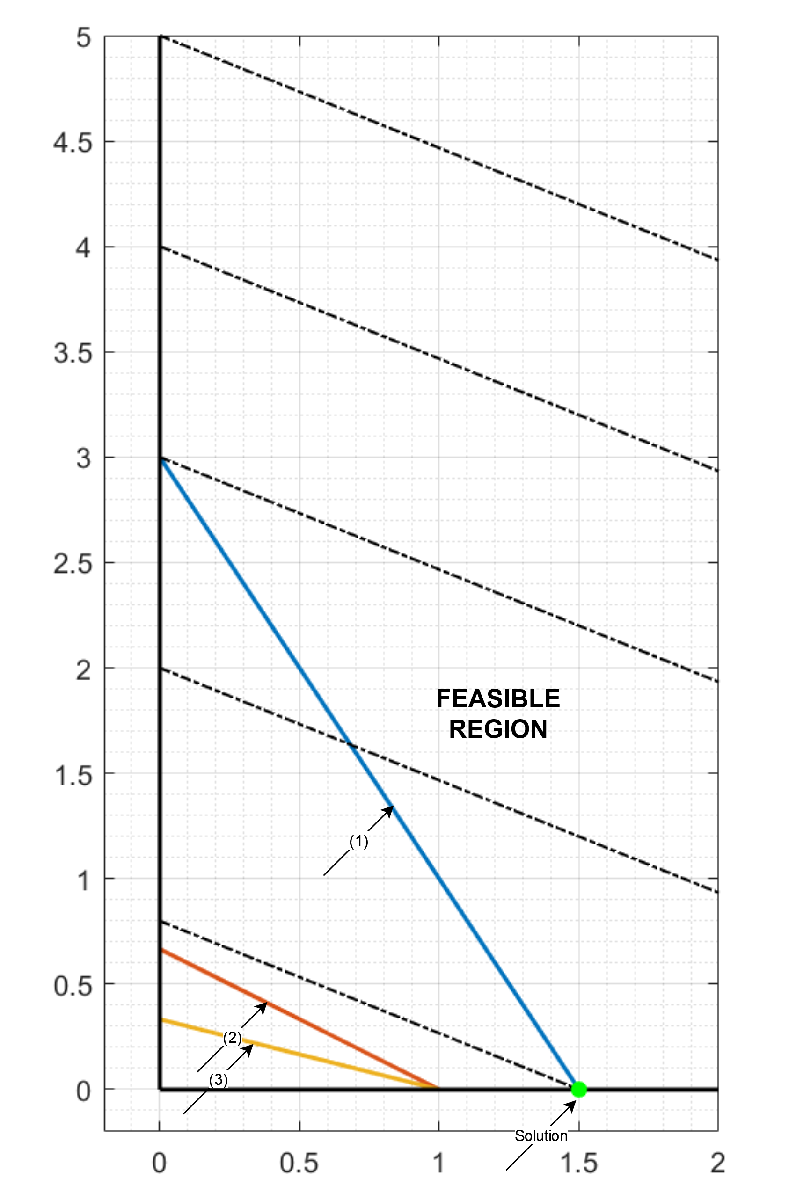

Figure 1.1

It is apperent from the figure that the optimal solution is located at the position (1.5, 0). Subsituting these values into the objective function of D:

  
$$z=-8y_1 -15y_2$$



$$z=-8\left(1\ldotp 5\right)-15\left(0\right)$$


z = -12

The same objective value is achieved, thus verifying the solution derived in part B and showing that the strong duality theorem holds.

**(d) Verify the complementary slackness theorem for the optimal solutions derived for P and D.**

The complementary slackness theorem states that: *if x and y are corresponding feasible solutions to a Primal-Dual pair of Linear Programming problems then both are optimal if and only if*

(4)       $y^T \left(\mathrm{Ax}-b\right)$ = 0

(5)     $x^T \left(A^T y-c\right)=0$

% Input solutions derived in earlier steps
y = [1.5; 0];
x = [4; 0; 0];

% C is the constraint values 
c = [3; 2; 1];

% Apply equations 4 and 5 detailed above
equ4 = y'*(A*x - b);
equ5 = x'*(A'*y - c);

if equ4 == 0 && equ5 == 0
    disp('Optimal solutions have been found!!')
else
    disp('Optimal solutions have not been found')
end

Optimal solutions have been found!!


**(e) Suppose now instead the primal problem P consists of two inequality constraints in n decision variables, and so takes the form**


$$\max \;\mathit{\mathbf{z}}=\sum_{\mathit{\mathbf{i}}}^{\mathit{\mathbf{n}}} {\mathit{\mathbf{c}}}_{\mathit{\mathbf{i}}\;} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$$


**subject to**

${\mathit{\mathbf{a}}}_{11} {\;\mathit{\mathbf{x}}}_1 +{\mathit{\mathbf{a}}}_{12\;} {\mathit{\mathbf{x}}}_2 +\cdots +{\mathit{\mathbf{a}}}_{1\mathit{\mathbf{n}}} {\;\mathit{\mathbf{x}}}_{\mathit{\mathbf{n}}\;} \le {\mathit{\mathbf{b}}}_1$,

${\mathit{\mathbf{a}}}_{21} {\;\mathit{\mathbf{x}}}_1 +{\mathit{\mathbf{a}}}_{22} {\;\mathit{\mathbf{x}}}_2 +\cdots +{\mathit{\mathbf{a}}}_{2\mathit{\mathbf{n}}} {\;\mathit{\mathbf{x}}}_{\mathit{\mathbf{n}}} \le {\mathit{\mathbf{b}}}_2$,

**and** ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \ge 0$** for i = 1, 2, . . . , n. Suppose n is large, and you may assume aij , bi, and **${\mathit{\mathbf{c}}}_{\mathit{\mathbf{i}}} \ge 0$** if you wish. Discuss the pros and cons of solving P versus its dual D, from the point of view of computational complexity.**

The dual problem swaps the number of constraint equations for the number of variables and vice versa. 

It can be solved computationally using the simplex method.

For both the primal and dual problems, the starting tableau size will be the same. However, given the large number of constraints in the dual, it is likely that some of these constraints will be redundant. Before intiating the simplex algorithm, the tableau can be reduced to creare a smaller matrix to be computed, and therefore reduce the computational complexity.